# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: September 4, 2020

- Location: Locomotion Laboratory

- Subject: BS

- Quarq calibration factor: 311

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 21.0

- Humidity (%): 50.1

- Pressure (mmHg): 634            

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 4;
code = {'BS'};
sex = {'F'};
age = 24;
mass = 130;
height = 1.65;

T = table(number,code,sex,age,mass,height)

## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.05; 0.1; 0.2];
listHang = listPerc * mass

### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

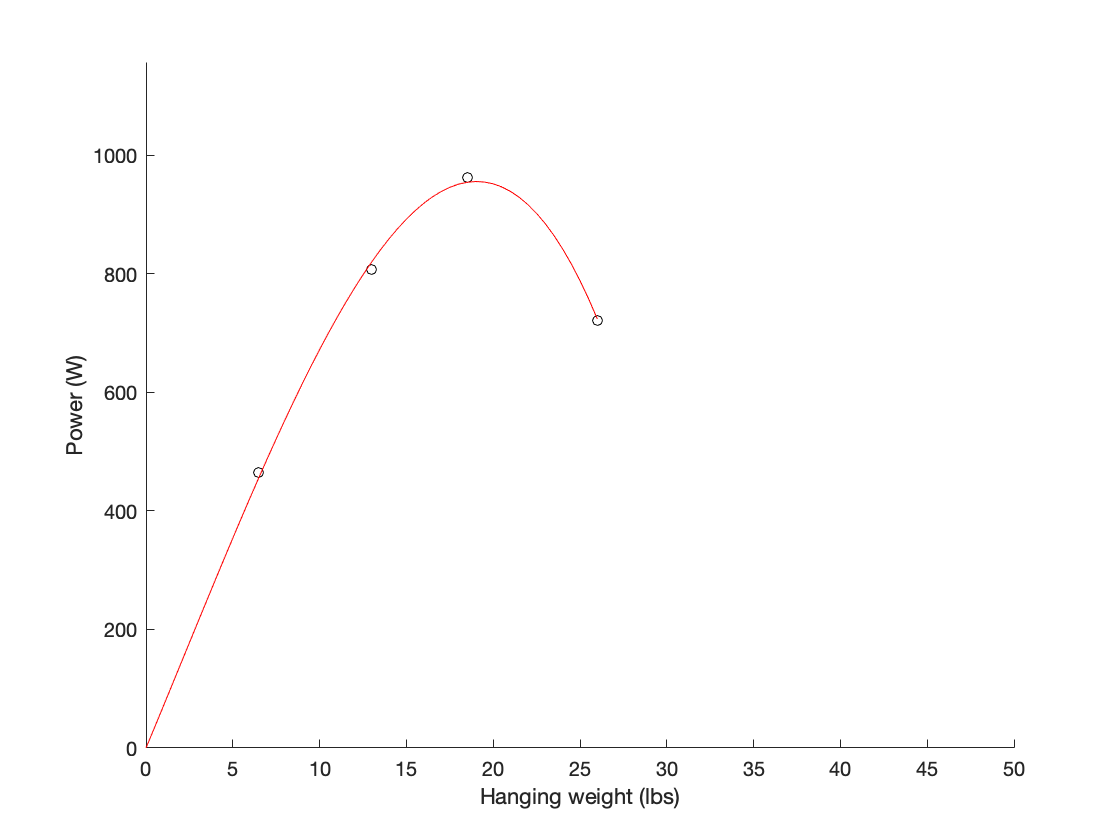

x = [6.5; 13; 18.5; 26]; % hanging weight
x_ = [149; 117; 110; 61]; % cadence
y = [464; 807; 963; 722]; % power output

% fit curve: power vs hang
[c, ~, ~] = fit(x,y,'poly3','Lower',[-Inf -Inf -Inf 0],'Upper',[Inf Inf Inf 0]);
% [c, ~, ~] = fit(x,y,'poly2');

new_x = 0:max(x)/(max(x)*2):max(x);
new_y = c.p1*new_x.^3 + c.p2*new_x.^2 + c.p3*new_x + c.p4;

% plot curve
scatter(x,y,25,'k','filled');
hold on
plot(new_x,new_y,'k-')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 955.66 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 19.00 Lbs 


### Randomize trial order within each block

randperm(3)
randperm(3)
randperm(3)

### Experimental results

Record results to array then convert to table.

data = [
    4, 1, 1, 18.5, 900, 105;
    4, 2, 1, 18.5, 871, 100;
    4, 3, 1, 18.5, 927, 108;
    4, 3, 2, 18.5, 897, 110;
    4, 1, 2, 18.5, 963, 110;
    4, 2, 2, 18.5, 879, 101;
    4, 2, 3, 18.5, 871, 103;
    4, 3, 3, 18.5, 917, 105;
    4, 1, 3, 18.5, 887, 105;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})
varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})